# Interpolación polinomial

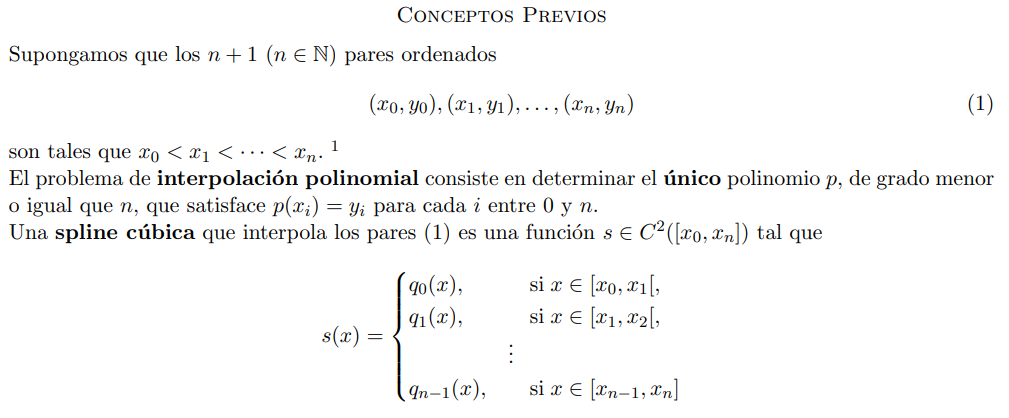

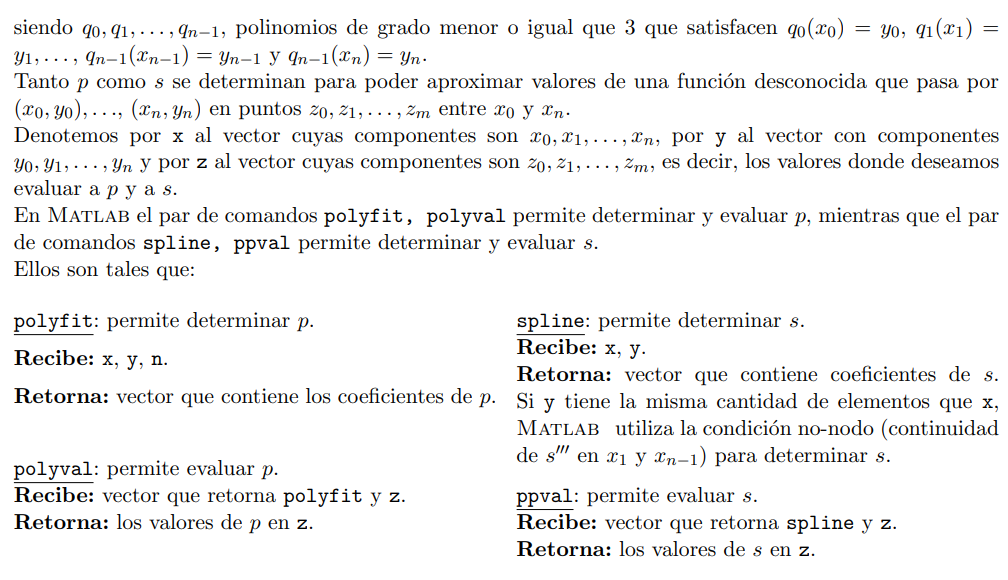

# Actividad 1

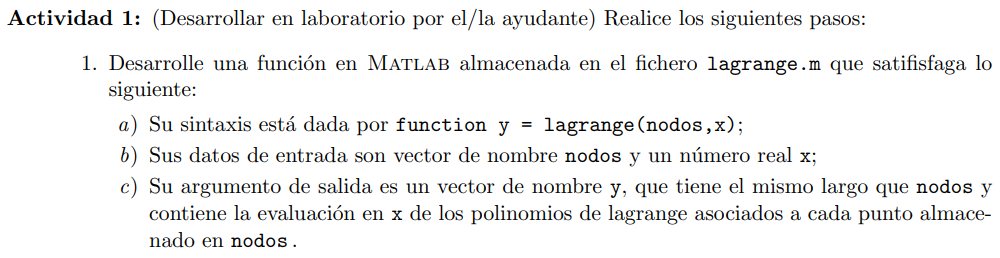

Antes de responder esta pregunta, recordemos que: dados los puntos $(x_0,y_0),\ (x_1,y_1),\ldots,(x_n,y_n)\in\mathbb{R}^n$, el interpolador de Lagrange se escribe asi:

donde

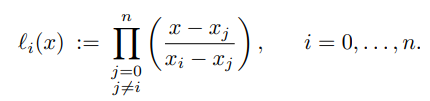

Esas dos igualdades son las que vamos a escribir en la funcion lagrange.

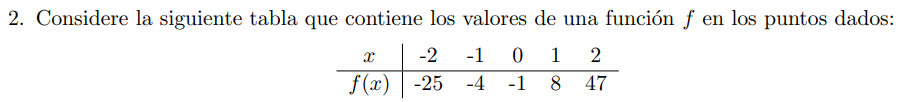

%datos
datox=[-2,-1,0,1,2]; fx=[-25,-4,-1,8,47];

Para ver si es que escribimos bien los datos en los vectores, podemos hacer esto

table(datox',fx')

ans = 5×2 table
    Var1    Var2
    ____    ____

     -2     -25 
     -1      -4 
      0      -1 
      1       8 
      2      47 


%puntos que queremos interpolar
X=-2:4/1000:2;

%calculos de los valores interpolados
n=length(X);
I=zeros(1,n);


for i=1:n
    y=lagrange(datox,X(i));
    I(i)=y*(fx)';
end

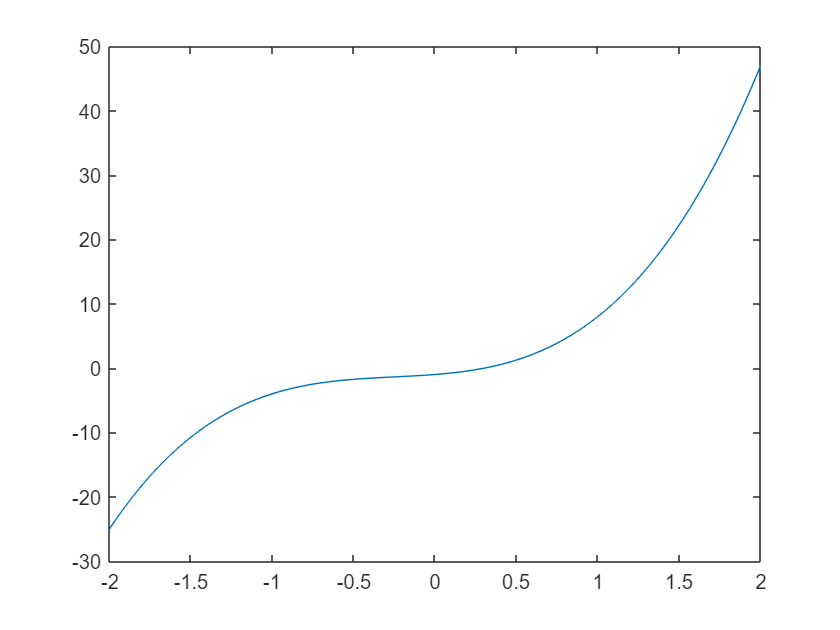

plot(X,I)

Tambien podemos plotear la funcion anterior con los datos

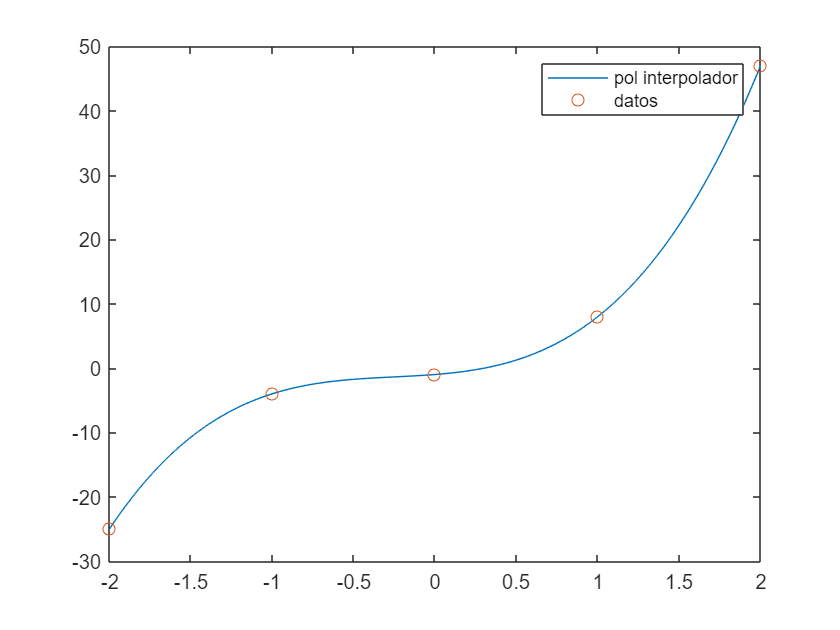

plot(X,I,datox,fx,'o')
legend('pol interpolador','datos')

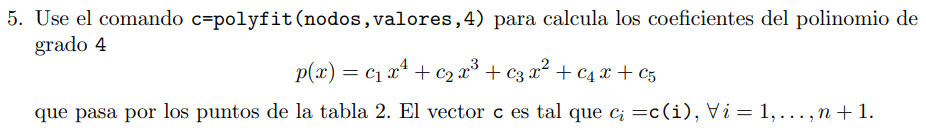

%c=polyfit(datox,fx,4);
c=polyfit(datox,fx,4)

c =    -0.0000    4.0000    3.0000    2.0000   -1.0000


p=polyval(c,X);

plot(X,p)

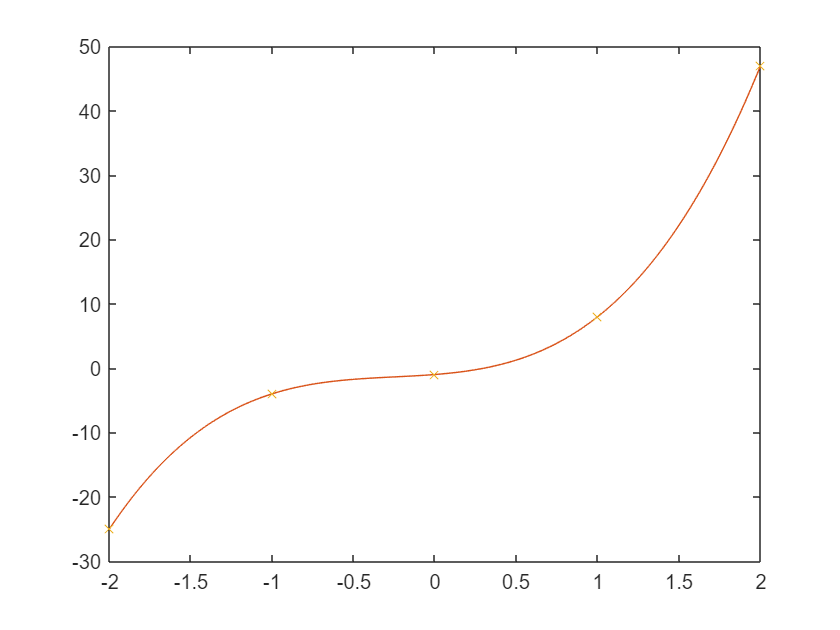

plot(X,I,X,p,datox,fx,'x')

Pero uno lo puede dejar mas bonito

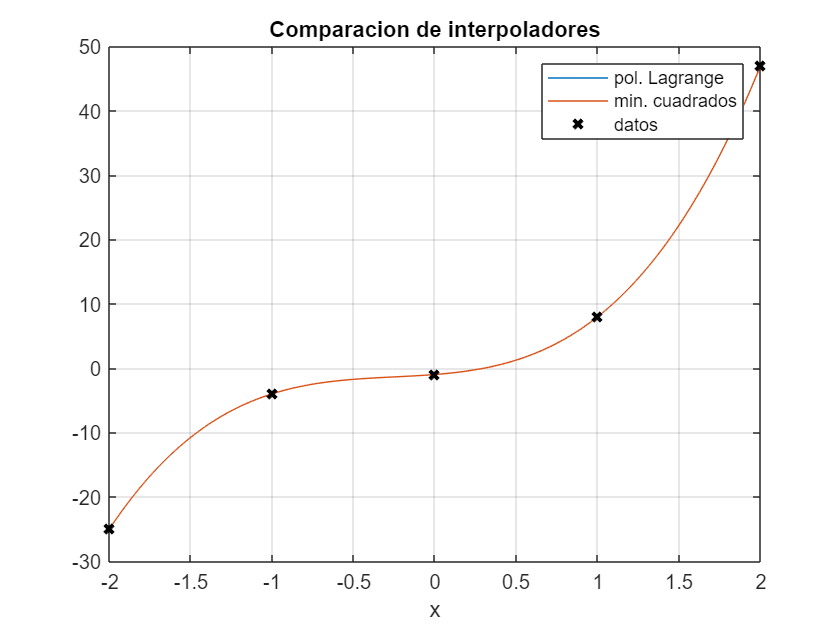

plot(X,I,X,p)
hold on
plot(datox,fx,'x','Linewidth',2,'Color','k')
hold off
grid on
title('Comparacion de interpoladores')
xlabel('x')
legend('pol. Lagrange','min. cuadrados','datos')